% Given hexadecimal color codes
hex_colors = {'#66156b', '#802575', '#98377e', '#af4a86', '#c45e8e', ...
    '#d77495', '#e78c9a', '#f4a59e', '#fcc0a1', '#ffdda1'};

% Initialize an empty array to store RGB values
rgb_values = zeros(numel(hex_colors), 3);

% Convert hexadecimal color codes to RGB decimal values
for i = 1:numel(hex_colors)
    hex = hex_colors{i}(2:end); % Remove the '#' character
    rgb_values(i, :) = sscanf(hex, '%2x%2x%2x') / 255; % Convert hex to RGB and normalize
end



% Define parameters
stad = [39.98364264	45.07701325;...
34.66886863	39.57113839;...
34.559		39.92424642;...
35.78986974		41.84354678;...
37.60185192		44.47998702];

rgb_hep = rgb_values([1 3 6 8 10],:)

rgb_hep =     0.4000    0.0824    0.4196
    0.5961    0.2157    0.4941
    0.8431    0.4549    0.5843
    0.9569    0.6471    0.6196
    1.0000    0.8667    0.6314



clf
% Generate x-values for plotting
alphas = [ 0.3 0.3 0.3 0.3 0.1]*2

alphas =     0.6000    0.6000    0.6000    0.6000    0.2000


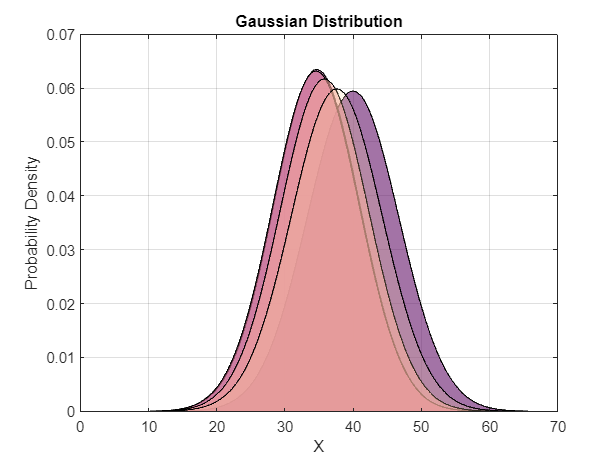

for i=1:5
    mu = stad(i,1);
    sigma = sqrt(stad(i,2));
x = linspace(mu - 4*sigma, mu + 4*sigma, 1000);
% Compute the probability density function (PDF) of the normal distribution
pdf_normal = normpdf(x, mu, sigma);

% Plot the Gaussian distribution as a filled plot wit transparency
fill(x, pdf_normal,rgb_hep(i,:), 'FaceAlpha', alphas(i));
hold on;

% Plot the PDF curve for reference
%plot(x, pdf_normal, 'b', 'LineWidth', 2);
xlabel('X');
ylabel('Probability Density');
title('Gaussian Distribution');
grid on;

end